# OptMeths_ex3

## Exercise 1


x_global = [0.46557; 2.1479];
x_local = [-1; -0.5];
x_saddle = [-1/3; -7/54];

options = optimset('Display', 'off');

[x_opt1, res1] = lsqnonlin(@obj_fun1, x_global, [], [], options);
fprintf('x_global -> Found: [%.5f, %.5f], Sum of the squares of the residuals: %e\n', x_opt1(1), x_opt1(2), res1);

x_global -> Found: [0.46557, 2.14790], Sum of the squares of the residuals: 4.584163e-23



[x_opt2, res2] = lsqnonlin(@obj_fun1, x_local, [], [], options);
fprintf('x_local  -> Found: [%.5f, %.5f], Sum of the squares of the residuals: %e (minimum)\n', x_opt2(1), x_opt2(2), res2);

x_local  -> Found: [-1.00000, -0.50000], Sum of the squares of the residuals: 5.000000e-01 (minimum)



function F = obj_fun1(x)
    F = zeros(2,1);
    F(1) = x(1)^3 + 3*x(1)^2 + 3*x(1) - x(2);
    F(2) = x(1)^2 + 2*x(1) - x(2) + 1;
end


## Exercise 2

x0 = [0; 0];
options = optimset('Display', 'iter');


[x_lsq, resnorm] = lsqnonlin(@obj_fun2, x0, [], [], options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3                 9                                9
     1          6          0.876096         1.34164            0.703      
     2          9          0.876096         1.03848            0.703      
     3         12          0.586368         0.25962            0.315      
     4         15          0.505267         0.25962           0.0769      
     5         18          0.505267         0.25962           0.0769      
     6         21          0.500258        0.064905           0.0194      
     7         24          0.500258        0.064905           0.0194      
     8         27          0.500045       0.0162262          0.00596      
     9         30          0.500045       0.0162262          0.00596      
    10         33          0.500006      0.00405656          0.00216      
    11         36          0.500003      

[x_fsol, fval] = fsolve(@obj_fun2, x0, options);


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3                   9                               9              1
     1          6              1.6691              1             1.41              1
     2          9            0.560306              1            0.236              1
     3         10            0.560306              1            0.236              1
     4         13            0.501035           0.25           0.0264           0.25
     5         14            0.501035           0.25           0.0264           0.25
     6         15            0.501035         0.0625           0.0264         0.0625
     7         18            0.500235       0.015625           0.0151         0.0156
     8         21            0.500009       0.015625          0.00432         0.0156
     9         22            0.500009       0.015625          0.


fprintf('\nResult lsqnonlin: [%.4f, %.4f], Rest: %e\n', x_lsq(1), x_lsq(2), resnorm);


Result lsqnonlin: [1.0000, -1.5000], Rest: 5.000000e-01


fprintf('Result fsolve:    [%.4f, %.4f], F(x) norm: %e\n', x_fsol(1), x_fsol(2), norm(fval));

Result fsolve:    [1.0000, -1.5000], F(x) norm: 7.071068e-01


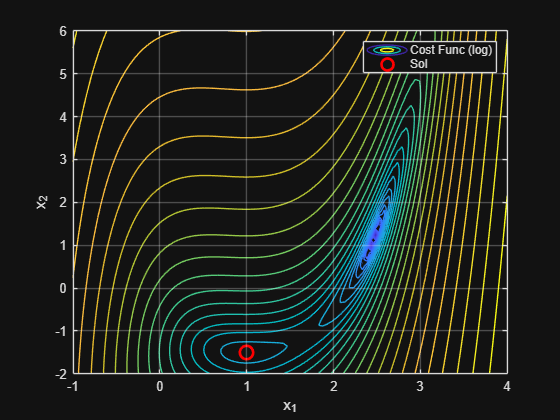


x1_vals = linspace(-1, 4, 100);
x2_vals = linspace(-2, 6, 100);
[X1, X2] = meshgrid(x1_vals, x2_vals);
Z = zeros(size(X1));

for i = 1:size(X1, 1)
    for j = 1:size(X1, 2)
        F = obj_fun2([X1(i,j); X2(i,j)]);
        Z(i,j) = sum(F.^2);
    end
end

figure;
contour(X1, X2, log10(Z + 1e-3), 30);
hold on;
plot(x_lsq(1), x_lsq(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('x_1'); ylabel('x_2');
legend('Cost Func (log)', 'Sol');
grid on;


    function F = obj_fun2(x)
        F = zeros(2,1);
        F(1) = x(1)^3 - 3*x(1)^2 + 3*x(1) - x(2) - 3;
        F(2) = x(1)^2 - 2*x(1) - x(2);
    end


## Exercise 3

x0 = [-5; -5];
options = optimset('Display', 'iter', 'TolFun', 1e-8);

[x_fsol, fval, exitflag] = fsolve(@obj_fun3, x0, options);


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             47071.2                        2.29e+04              1
     1          6             12003.4              1         5.75e+03              1
     2          9             3147.02              1         1.47e+03              1
     3         12             854.452              1              388              1
     4         15             239.527              1              107              1
     5         18             67.0412              1             30.8              1
     6         21             16.7042              1             9.05              1
     7         24             2.42788              1             2.26              1
     8         27            0.032658       0.759511            0.206            2.5
     9         30         7.03149e-06       0.111927          0.

[x_lsq, resnorm] = lsqnonlin(@obj_fun3, x0, [], [], options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3           47071.2                         2.29e+04
     1          6           6527.47         1.45207         3.09e+03      
     2          9           918.372         1.49186              418      
     3         12            127.74         1.55326             57.3      
     4         15           14.9153         1.57591             8.26      
     5         18          0.779052         1.27662             1.14      
     6         21        0.00372453        0.484658           0.0683      
     7         24       9.21619e-08       0.0385552         0.000336      
     8         27       5.66133e-17     0.000193707         8.34e-09      

Local minimum found.

Optimization completed because the 


fprintf('\nfsolve:    [%.5f, %.5f] (Exitflag: %d)\n', x_fsol(1), x_fsol(2), exitflag);


Wynik fsolve:    [0.56714, 0.56714] (Exitflag: 1)


fprintf('lsqnonlin: [%.5f, %.5f] (Resnorm: %e)\n', x_lsq(1), x_lsq(2), resnorm);

Wynik lsqnonlin: [0.56714, 0.56714] (Resnorm: 5.661325e-17)



function F = obj_fun3(x)
    F = zeros(2,1);
    F(1) = 2*x(1) - x(2) - exp(-x(1));
    F(2) = -x(1) + 2*x(2) - exp(-x(2));
end
